A = load("MEASUREA.DAT")

A =     1.0000         0         0         0
    2.0000    0.5000   -0.0018    0.0046
    3.0000    1.0000    0.0056    0.0023
    4.0000    0.5000    0.0320   -0.0011
    5.0000         0    0.0744    0.0041
    6.0000         0    0.1134    0.0024
    7.0000         0    0.1375    0.0012
    8.0000   -0.3333    0.1471   -0.0020
    9.0000   -0.6667    0.1396   -0.0065
   10.0000   -1.0000    0.0995   -0.0050


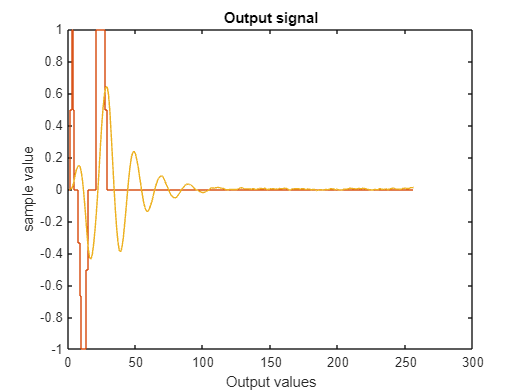

t = A(:,1); % output
u = A(:,2); % input
y = A(:,3); % output
% n = A(:,4); % noise


figure
plot(t, y)
xlabel("number of samples")
ylabel("sample value")
title("Time column")
hold on 
stairs(t, u)
xlabel("Input values")
ylabel("sample value")
title("Input signal")

plot(A(:,3))
xlabel("Output values")
ylabel("sample value")
title("Output signal")

n = 2;
d = 0;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

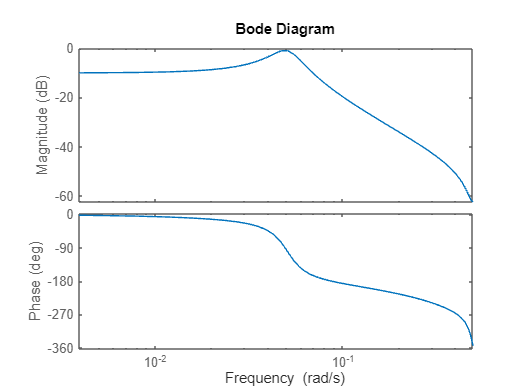


y_short = y((n+d+1):end);
Th = psi \ y_short;
T = 6.3;
G = tf([Th(3) Th(4)],[1 Th(1) Th(2)], T);
% G = tf([Th(4) Th(5) Th(6)],[1 Th(1) Th(2) Th(3)], T);


N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector

figure
bode(G,v);

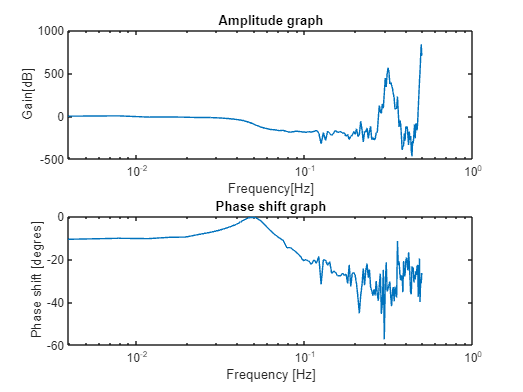

[MAG, PH]=bode(G, v);
MAG = MAG(:);
PH = PH(:);
FT_input = fft(u);
FT_output = fft(y);

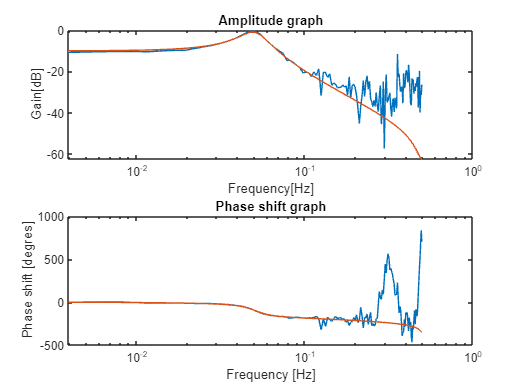

G_jw = FT_output ./ FT_input;
faza = unwrap(angle(G_jw));

figure
subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:end/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(faza(1:end/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

## 4

%verificiraj diskretni model z lsim
%merjeni in simulirani izhodni signal na istem diagramu
%kovariančna matrika in standardna deviacija ocen parametrov

% Izračunajte ocenjene vrednosti
theta_hat = inv(psi'*psi)*psi'*y_short;
y_hat = psi * theta_hat; % predpostavimo, da imate ocene parametrov theta_hat

% Izračunajte rezidualne vrednosti
residuals = y_short - y_hat;

% Izračun sume kvadratov napak
SSE = sum(residuals(d+1:end).^2);

% Izračun Psi^T * Psi
PsiTPsi = psi(d+1:end,:)' * psi(d+1:end,:);

% Izračun kovariančne matrike za ocene parametrov
cov_theta_hat = (SSE / (N - n - d)) * inv(PsiTPsi);